d_W =                    0
   2.735705242471605
   5.440130013623239
   8.084088592745367
  10.611163501192859
  12.912303986323572
  14.776631361073123
  15.797542367095788
  15.175705669585286
  11.538684492767560


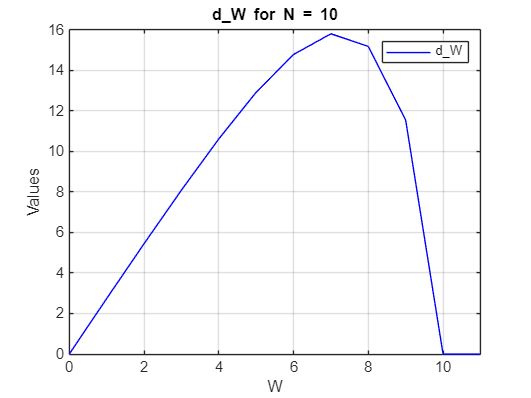

d_W = 1.0e+02 *

                   0
   0.027692307692302
   0.055384615384598
   0.083076923076884
   0.110769230769149
   0.138461538461374
   0.166153846153522
   0.193846153845521
   0.221538461537233
   0.249230769228388


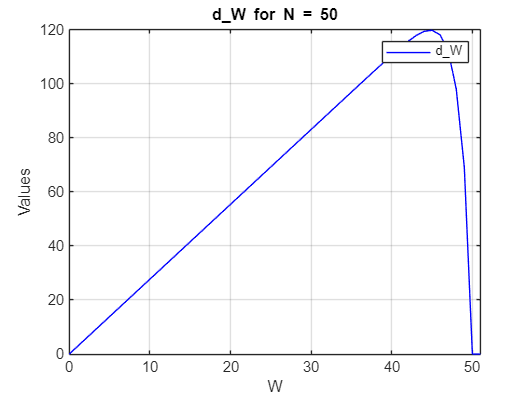

d_W = 1.0e+02 *

                   0
   0.027692307692308
   0.055384615384615
   0.083076923076923
   0.110769230769231
   0.138461538461538
   0.166153846153846
   0.193846153846154
   0.221538461538461
   0.249230769230769


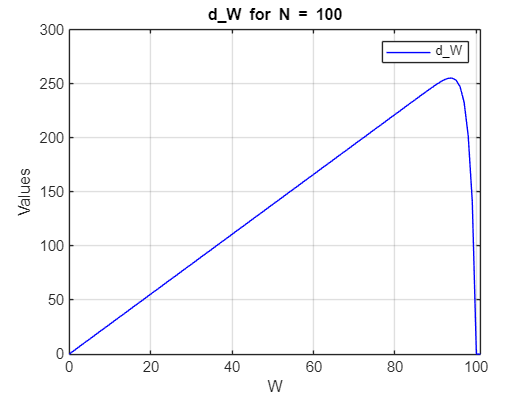

format long

N_values = [10, 50, 100]; 
n = length(N_values);
p_1 = 5/18;
p_2 = 1/36;
q = 25/36;


for i = 1:n
    N = N_values(i);

P = zeros(N+2, N+2);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 

for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
end


% Extract Q and R matrices
Q = P(2:N, 2:N);        % Transient-to-transient transitions
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2)];  % Transient-to-absorbing transitions

% Fundamental matrix
I = eye(size(Q));
F = inv(I - Q);
m = length(F(:,1));
c = ones (m, 1);
D = F*c;
D_full = [0; D; 0; 0];

% Extract ruin probabilities
d_W = double(D_full)
    figure;
    plot(0:N+1, d_W, 'b', 'DisplayName', 'd\_W');
    xlabel('W');
    ylabel('Values');
    legend;
    title(['d\_W for N = ', num2str(N)]);
    grid on;
    xlim([0 N+1])
end